# Project 4 (Aerospace Altitude and Speed Profile Analyzer)

%{
Analyze a flight profile across phases
   originally from ES115 Engineering Computer Applications, Module 3
   project bank, project 4
Author: Tori Testa
Version: 1.0
Date: 2026-04-07
Purpose:
   -
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   - 
%}

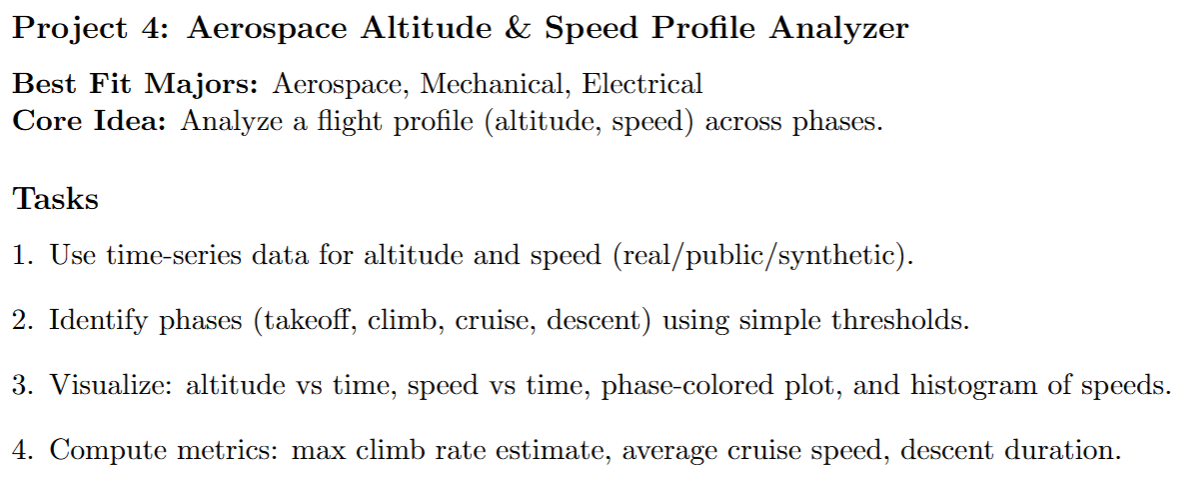

clc
clear

% load time-series data for altitude and speed
load('flight_data.csv')
t = flight_data(:, 1);
alt = flight_data(:, 2);
spd = flight_data(:, 3);

% identify flight phases using threshholds
vy = [0; (diff(alt))./(diff(t))];

takeoff = alt < 100;
climb = vy > 2;
cruise = abs(vy) < 5 & alt > 1000;
descent = vy < -2;

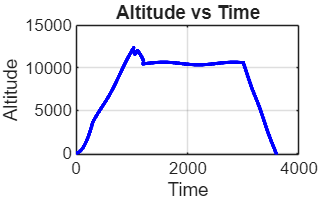

% creates an altitude vs time plot
plot(t, alt, 'b-', 'LineWidth', 2) % makes the line blue with a width of 2
title('Altitude vs Time') % titles the graph
ylabel('Altitude') % labels the y axis altitude
xlabel('Time') % labels the x axis time
grid on % turns on the grid lines

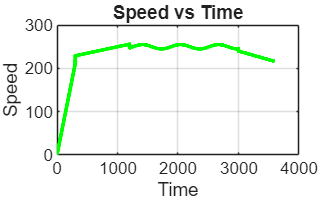

% creates a speed vs time plot
plot(t, spd, 'g-', 'LineWidth', 2) % makes the line green with a width of 2
title('Speed vs Time') % titles the graph
ylabel('Speed') % labels the y axis speed
xlabel('Time') % labels the x axis time
grid on % turns on the grid lines

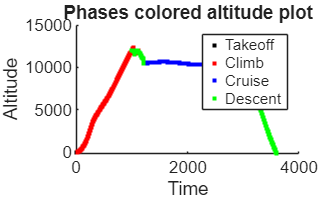

% phase colored altitude plot
figure
hold on
plot(t(takeoff), alt(takeoff), 'k.', 'DisplayName', 'Takeoff')
plot(t(climb), alt(climb), 'r.', 'DisplayName', 'Climb')
plot(t(cruise), alt(cruise), 'b.', 'DisplayName', 'Cruise')
plot(t(descent), alt(descent), 'g.', 'DisplayName', 'Descent')
hold off
title('Phases colored altitude plot')
xlabel('Time')
ylabel('Altitude')
legend

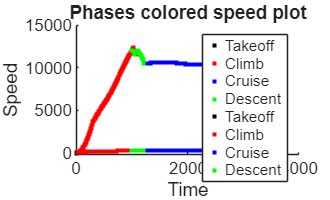

% phase colored speed plot
hold on
plot(t(takeoff), spd(takeoff), 'k.', 'DisplayName', 'Takeoff')
plot(t(climb), spd(climb), 'r.', 'DisplayName', 'Climb')
plot(t(cruise), spd(cruise), 'b.', 'DisplayName', 'Cruise')
plot(t(descent), spd(descent), 'g.', 'DisplayName', 'Descent')
hold off
title('Phases colored speed plot')
xlabel('Time')
ylabel('Speed')
legend
hold off

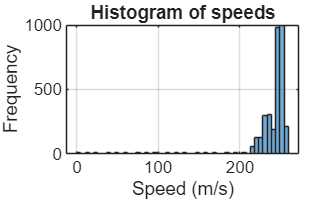

% histogram of speeds
histogram(spd,50)
title('Histogram of speeds')
xlabel('Speed (m/s)')
ylabel('Frequency')
grid on

%max climb rate estimate
maxClimb = max(vy);
fprintf('The maximum climb rate is: %g m/s', maxClimb)

The maximum climb rate is: 60.8133 m/s

% average cruise speed
avgS = mean(cruise); % determines the average cruising speed
fprintf('The average cruising speed for the flight is %g m/s', avgS)

The average cruising speed for the flight is 0.499306 m/s

% descent duration
mean_t = mean(diff(t));
Tdescent = sum(descent) * mean_t;
fprintf('The duration of descent is %g', Tdescent)

The duration of descent is 700